# Задание 1

\section{Задача стабилизации с идеальным дифференцирующим звеном}

Рассмотрим объект управления 2-го порядка, заданный дифференциальным уравнением


$$a_2\ddot{y} + a_1\dot{y} + a_0y = u. \quad (1)$$


Придумаем такие коэффициенты $a_2$, $a_1$ и $a_0$, чтобы она содержала хотя бы один неустойчивый полюс. Зададимся ненулевым $\dot{y}(0)$ ($y(0)$ примем равным 0) и выполним моделирование свободного движения разомкнутой системы $y_{\text{раз}}(t)$.

Рассмотрим регулятор вида 


$$u = k_0y + k_1\dot{y} \quad (2)$$


и построим структурную схему замкнутой системы, состоящей из объекта управления (1) и регулятора (2), в режиме стабилизации. Определим, при каких значениях параметров $k_0$ и $k_1$ замкнутая система будет устойчивой.

Зададимся конкретными значениями параметров $k_0$ и $k_1$, обеспечивающими асимптотически устойчивую замкнутую систему, и выполним моделирования движения замкнутой системы $y_{\text{з}}(t)$ с начальными условиями, выбранными в рамках предыдущего моделирования. При моделировании в программной среде MATLAB/Simulink для получения производной $\dot{y}(t)$ используем блок Derivativ, основанный на использовании конечной разности с малым шагом $\Delta t$


$$\dot{y}(t) \approx \frac{y(t) - y(t - \Delta t)}{\Delta t}.$$


Сравним результаты экспериментов и сделаем выводы.

Найдем подходящие коэффициенты:

$a_2\lambda^2+a_1\lambda+a_0=0$, пусть $a_0=-3, a_1=-2, a_2=1\Rightarrow(\lambda-3)(\lambda+1)=0, \lambda_1=-1, \lambda_2=3$.

Полюс $\lambda_2=3$ неустойчив по корневому критерию. Возьмём $\dot{y}(0)=4$.

Построим структурную схему (см. рис. ???):


$$a_2p^2y+a_1py+a_0y=u\Rightarrow
y=\frac{1}{a_2p}\left(\frac{1}{p}(u-a_0y)-a_1y\right)$$


???РИСУНОК???

Выполним моделирование (см. рис. ???).

???РИСУНОК???

Теперь построим структурную схему с регулятором $u = k_0y + k_1\dot{y}$ (см. рис. ???):

???РИСУНОК???

Определим при каких коэффициентах $k_i$ система будет устойчивой:


$$a_2\ddot{y} + a_1\dot{y} + a_0y = k_0y + k_1\dot{y}\Rightarrow
a_2\ddot{y} + (a_1-k_1)\dot{y} + (a_0-k_0)y=0\
$$


По теореме Стодолы (для случая систем не выше второго порядка, как у нас), система устойчива, если все коэффициенты характеристического полинома строго положительны, следовательно, для ассимптотической устойчивости:


$$a_2>0,\quad a_1-k_1>0,\quad a_0-k_0>0\Rightarrow k_1<-2,\quad k_0<-3$$


Возьмём $k_0 = -5, k_1 = -4$. Выполним моделирование (см. рис. ???).

???РИСУНОК???

**Выводы**

 В данном задании мы сначала построили неустойчивую систему (при свободном движении), после чего воспользовались теоремой Стодолы для нахождения коэффициентов для регулятора, которые могут сделать замкнутую систему устойчивой и выполнили моделирования для системы с регулятором. Результаты сошлись с теоретическими ожиданиями. Это довольно наглядная и простая демонстрация того, как работает простейший регулятор.

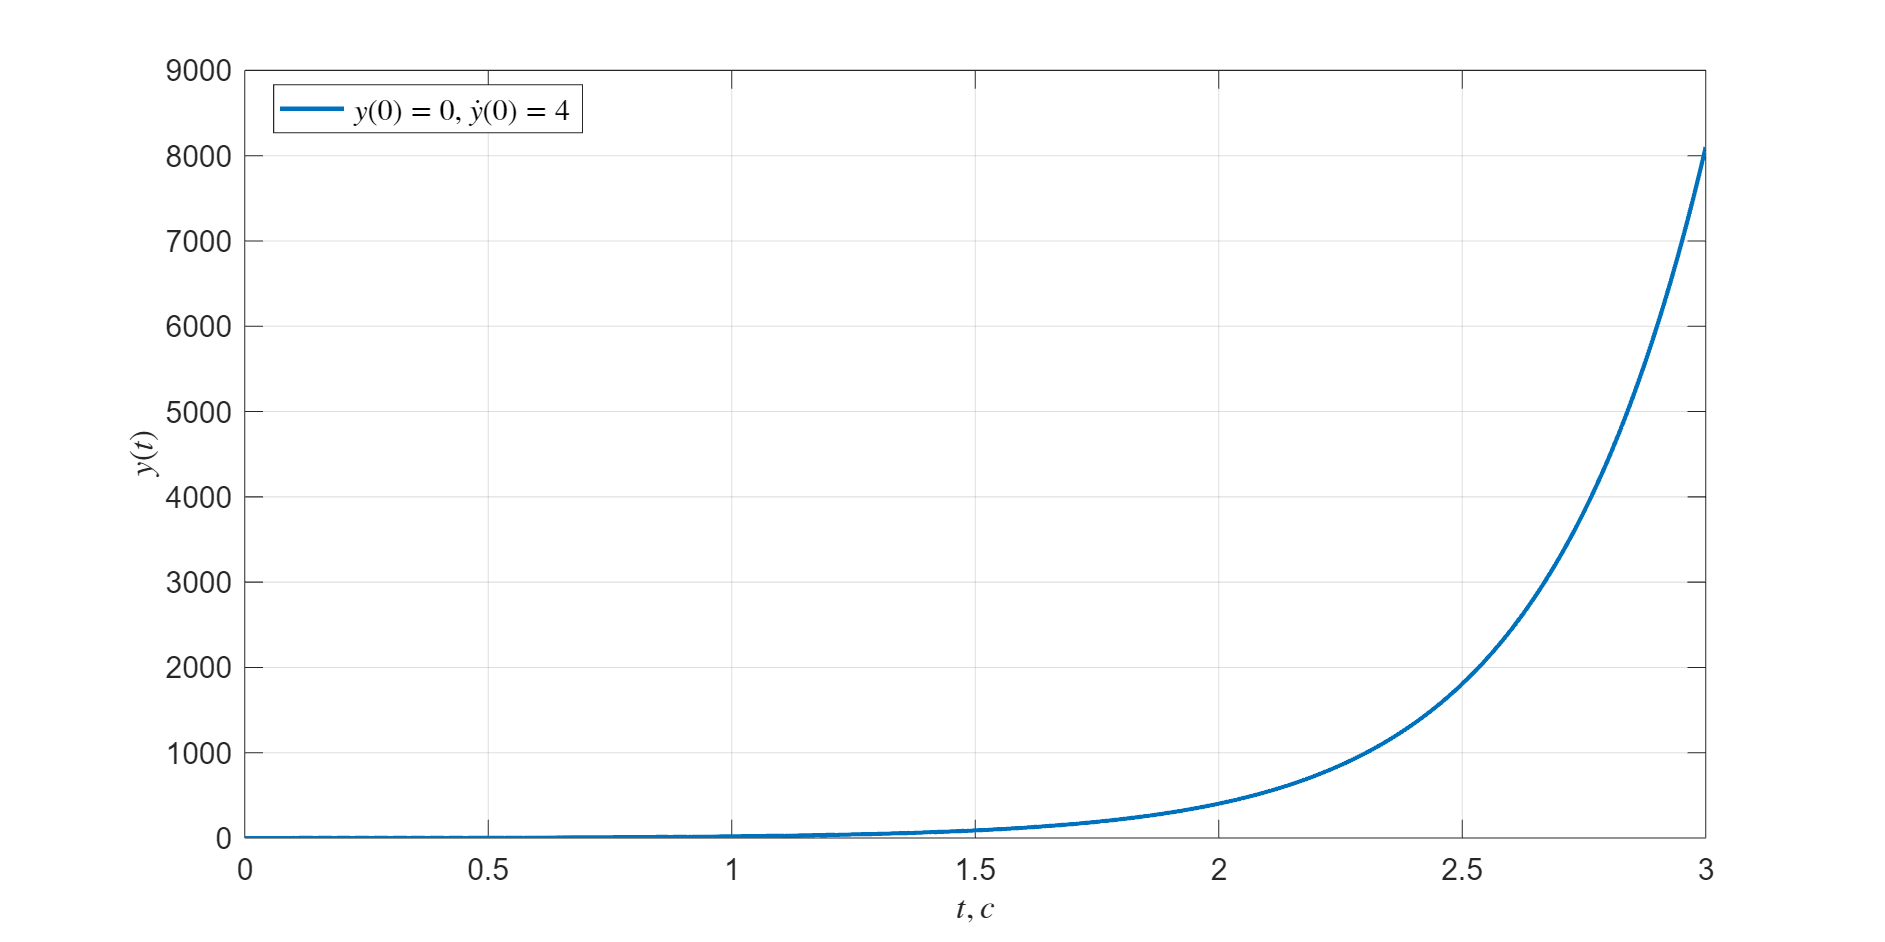

a_0 = -3;
a_1 = -2;
a_2 = 1;

simtime = 3;
plot_1 = sim("lab4_1.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', 0, 4))
grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
exportgraphics(gcf, "images/plot_1.png", Resolution=200)

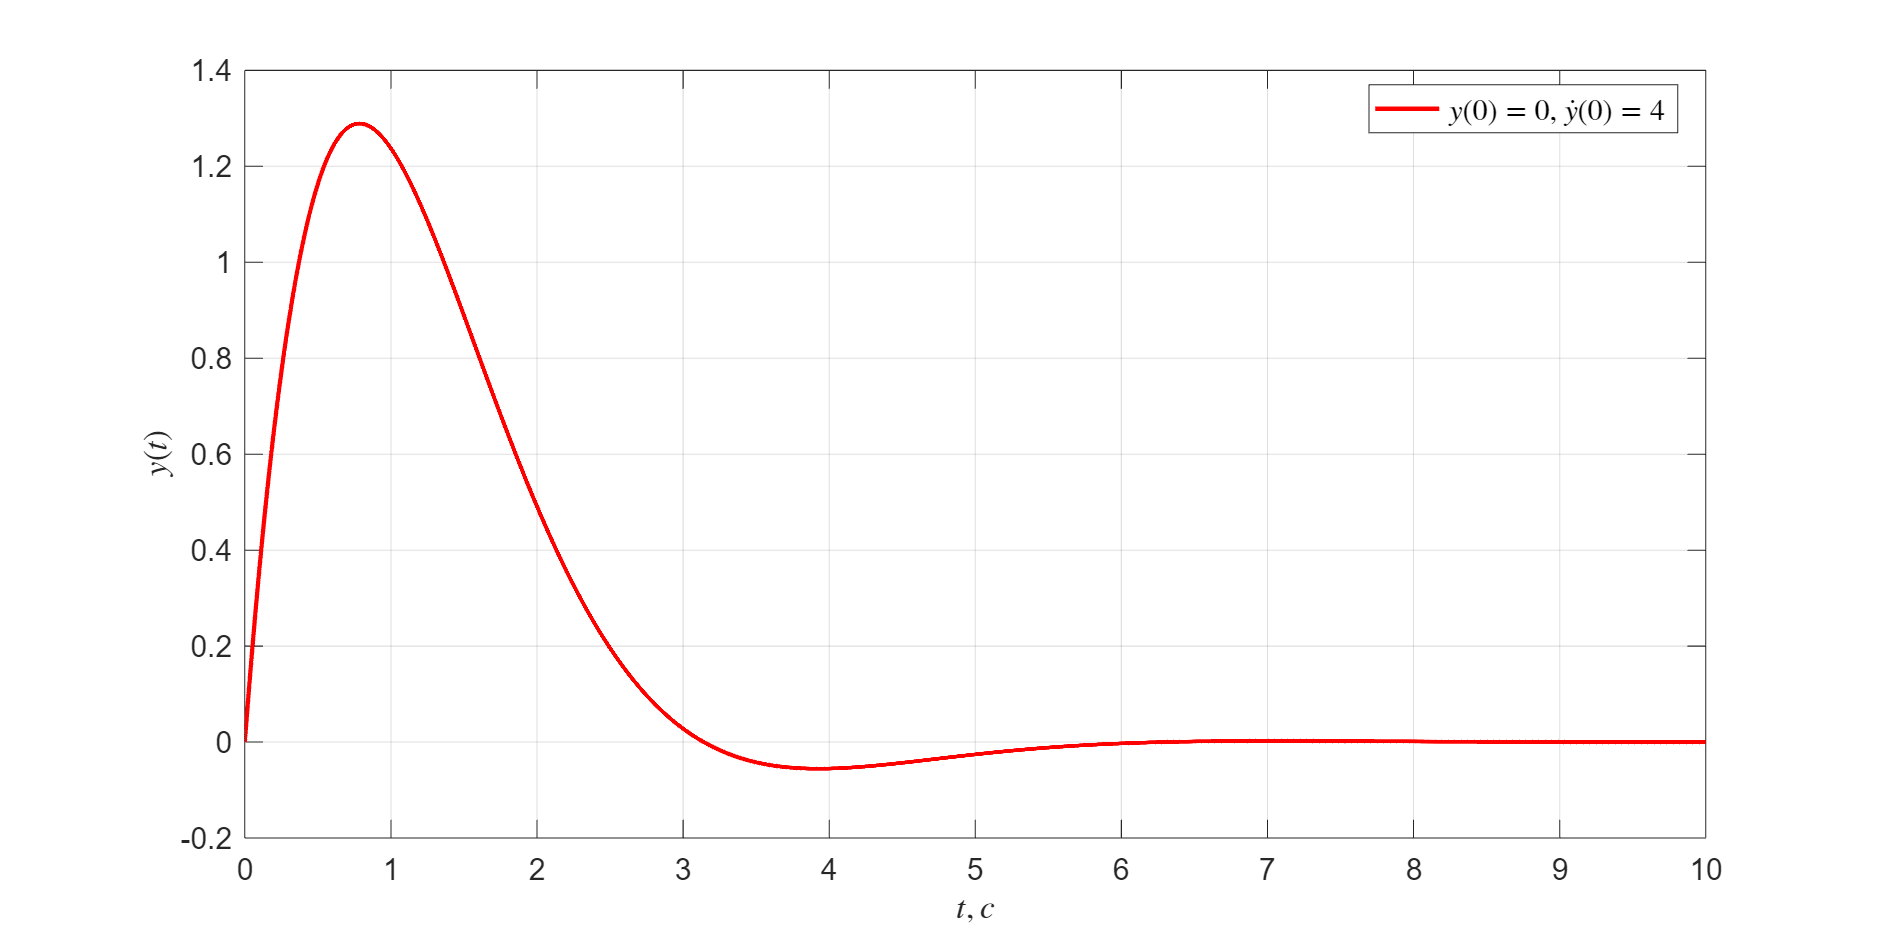

k_0 = -5;
k_1 = -4;

simtime = 10;
plot_1 = sim("lab4_1z.slx", simtime);
plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, color="red", LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', 0, 4))
grid on;
legend(Location="best", FontSize=14, Interpreter="latex");
xlabel("$t, c$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");
set(gcf, Position=[100, 100, 1200, 600]);   
set(gca, FontSize=14);
exportgraphics(gcf, "images/plot_1z.png", Resolution=200)